# Using ICA to reduce artefacts

## **Introduction**

This section will show how to use an independent component analysis (ICA) approach to suppress ocular and cardiac artifacts. This will be  done by first performing an ICA decomposition of the data after which the components reflecting the artifacts are identified manually. As a last step the artifact components are 'projected out'.

### **Question 1**

Why might ICA rather than principle component analysis (PCA) be applied to identify the individual components? 

## **Preparation**

Initialize FiedTrip.

ft_defaults

Set the path and the filenames of the FIF files. We will use the MaxFiltered data.

data_path = 'C:\YOUR_DATA_PATH';

dataset{1,1}='training_rawsss-1.fif';
dataset{1,2}='training_rawsss-2.fif';

Read the trials using the gradiometer channels only:

for i=1:length(dataset)
cfg  = [];
cfg.dataset = [data_path,char(dataset{1,i})];  
cfg.trialfun = 'ft_trialfun_general';  
cfg.trialdef.eventtype  = 'STI101';  
cfg.trialdef.eventvalue = [21 22];  
cfg.trialdef.prestim = 2.5;  
cfg.trialdef.poststim = 2;  
cfg  = ft_definetrial(cfg);   
cfg.channel = {'MEGGRAD'};  
cfg.demean = 'yes';    
data{i,1}  = ft_preprocessing(cfg); 
end

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'C:\Users\Tamas\Documents\training_rawsss-1.fif'



Copyright (c) 2011, Matti Hamalainen and Alexandre Gramfort
All rights reserved.

Redistribution and use in source and binary forms, with or without
modification, are permitted provided that the following conditions are met:
    * Redistributions of source code must retain the above copyright
      notice, this list of conditions and the following disclaimer.
    * Redistributions in binary form must reproduce the above copyright
      notice, this list of conditions and the following disclaimer in the
      documentation and/or other materials provided with the distribution.
    * Neither the name of the Massachusetts General Hospital nor the
      names of its contributors may be used to endorse or promote products
      derived from this software without specific prior written permission.

THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND
ANY EXPRESS OR IMPLIED WARRANTIES, I

	306 MEG channel locations transformed
Reading C:\Users\Tamas\Documents\training_rawsss-1.fif ...
Opening raw data file C:\Users\Tamas\Documents\training_rawsss-1.fif...
	Range : 208000 ... 1664999  =    208.000 ...  1664.999 secs
Ready.
processing channel { 'MEG0112' 'MEG0113' 'MEG0122' 'MEG0123' 'MEG0132' 'MEG0133' 'MEG0142' 'MEG0143' 'MEG0212' 'MEG0213' 'MEG0222' 'MEG0223' 'MEG0232' 'MEG0233' 'MEG0242' 'MEG0243' 'MEG0312' 'MEG0313' 'MEG0322' 'MEG0323' 'MEG0332' 'MEG0333' 'MEG0342' 'MEG0343' 'MEG0412' 'MEG0413' 'MEG0422' 'MEG0423' 'MEG0432' 'MEG0433' 'MEG0442' 'MEG0443' 'MEG0512' 'MEG0513' 'MEG0522' 'MEG0523' 'MEG0532' 'MEG0533' 'MEG0542' 'MEG0543' 'MEG0612' 'MEG0613' 'MEG0622' 'MEG0623' 'MEG0632' 'MEG0633' 'MEG0642' 'MEG0643' 'MEG0712' 'MEG0713' 'MEG0722' 'MEG0723' 'MEG0732' 'MEG0733' 'MEG0742' 'MEG0743' 'MEG0812' 'MEG0813' 'MEG0822' 'MEG0823' 'MEG0912' 'MEG0913' 'MEG0922' 'MEG0923' 'MEG0932' 'MEG0933' 'MEG0942' 'MEG0943' 'MEG1012' 'MEG1013' 'MEG1022' 'MEG1023' 'MEG1032' 'MEG1033' '

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'C:\Users\Tamas\Documents\training_rawsss-2.fif'
	306 MEG channel locations transformed
Reading C:\Users\Tamas\Documents\training_rawsss-2.fif ...
Opening raw data file C:\Users\Tamas\Documents\training_rawsss-2.fif...
	Range : 1665000 ... 3098999  =   1665.000 ...  3098.999 secs
Ready.
reading the events from 'C:\Users\Tamas\Documents\training_rawsss-2.fif'
	306 MEG channel locations transformed
Reading C:\Users\Tamas\Documents\training_rawsss-2.fif ...
Opening raw data file C:\Users\Tamas\Documents\training_rawsss-2.fif...
	Range : 1665000 ... 3098999  =   1665.000 ...  3098.999 secs
Ready.
Reading 1665000 ... 3098999  =   1665.000 ...  3098.999 secs... [done]
Reading 1665000 ... 3098999  =   1665.000 ...  3098.999 secs... [done]
found 4129 events
created 172 trials
the call to "ft_definetrial" took 16 seconds


	306 MEG channel locations transformed
Reading C:\Users\Tamas\Documents\training_rawsss-2.fif ...
Opening raw data file C:\Users\Tamas\Documents\training_rawsss-2.fif...
	Range : 1665000 ... 3098999  =   1665.000 ...  3098.999 secs
Ready.
processing channel { 'MEG0112' 'MEG0113' 'MEG0122' 'MEG0123' 'MEG0132' 'MEG0133' 'MEG0142' 'MEG0143' 'MEG0212' 'MEG0213' 'MEG0222' 'MEG0223' 'MEG0232' 'MEG0233' 'MEG0242' 'MEG0243' 'MEG0312' 'MEG0313' 'MEG0322' 'MEG0323' 'MEG0332' 'MEG0333' 'MEG0342' 'MEG0343' 'MEG0412' 'MEG0413' 'MEG0422' 'MEG0423' 'MEG0432' 'MEG0433' 'MEG0442' 'MEG0443' 'MEG0512' 'MEG0513' 'MEG0522' 'MEG0523' 'MEG0532' 'MEG0533' 'MEG0542' 'MEG0543' 'MEG0612' 'MEG0613' 'MEG0622' 'MEG0623' 'MEG0632' 'MEG0633' 'MEG0642' 'MEG0643' 'MEG0712' 'MEG0713' 'MEG0722' 'MEG0723' 'MEG0732' 'MEG0733' 'MEG0742' 'MEG0743' 'MEG0812' 'MEG0813' 'MEG0822' 'MEG0823' 'MEG0912' 'MEG0913' 'MEG0922' 'MEG0923' 'MEG0932' 'MEG0933' 'MEG0942' 'MEG0943' 'MEG1012' 'MEG1013' 'MEG1022' 'MEG1023' 'MEG1032' 'MEG1033' 

Append the two data files:

cfg=[];
cfg.keepsampleinfo='no';
data_planar=ft_appenddata(cfg,data{:});

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds
the call to "ft_appenddata" took 0 seconds


Select the trials and channels which were kept after the first round of visual artifact rejection:

trl=[data_path,'trl_keep.mat']; 
load(trl)
chan=[data_path,'chan_keep.mat']; 
load(chan)
cfg=[];
cfg.trials=trl_keep;
cfg.channel=chan_keep;
planar_rjv1=ft_selectdata(cfg,data_planar);

the call to "ft_selectdata" took 0 seconds


## **Downsampling**

In order to do the ICA decomposition efficiently, we will first downsample the data to 200 Hz. Note that we will eventually apply the projection to the non-downsampled data.

cfg=[]; 
cfg.resamplefs = 200;   
planar_resamp = ft_resampledata(cfg, planar_rjv1);

the input is raw data with 204 channels and 310 trials
the call to "ft_selectdata" took 0 seconds
resampling data
resampling data in trial 310 from 310

original sampling rate = 1000 Hz
new sampling rate = 200 Hz
the call to "ft_resampledata" took 9 seconds


Then, we apply a 1 - 40 Hz  bandpass filter. The 1 Hz highpass filter is important for removing slow drifts which otherwise would make the ICA decomposition less efficient. We also apply padding around our trial data (3 sec on each side of each trial) to reduce filtering artifacts.

cfg=[];
cfg.hpfreq=1;
cfg.lpfreq=40;
cfg.padding=10.5;
cfg.padtype='zero';
planar_filt=ft_preprocessing(cfg, planar_resamp);

 In fixsampleinfo at line 94
 In ft_datatype_raw at line 148
 In ft_checkdata at line 277
 In ft_preprocessing at line 288



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 277
 In ft_preprocessing at line 288

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 310 from 310

the call to "ft_preprocessing" took 0 seconds


## **ICA Step 1 - ICA Decomposition**

The first step when MaxFilter has been applied to the data is to determine the rank of the data. MaxFiltering leads to large dimension reduction of the data matrix. The computation of the ICA components can slow down drastically when this reduction is not accounted for. To address this issue, we will calculate the rank of the data using the 'rank' function. In this case it will suffice to use data of the first trial only. Note, when MaxFilter or other dimension reduction techniques are not applied, calculating and specifying the rank is not necessary.  

data_rank= rank(planar_filt.trial{1}*planar_filt.trial{1}');

We can also plot the singular values and look for the first large cliff to identify the effective data rank after MaxFiltering.

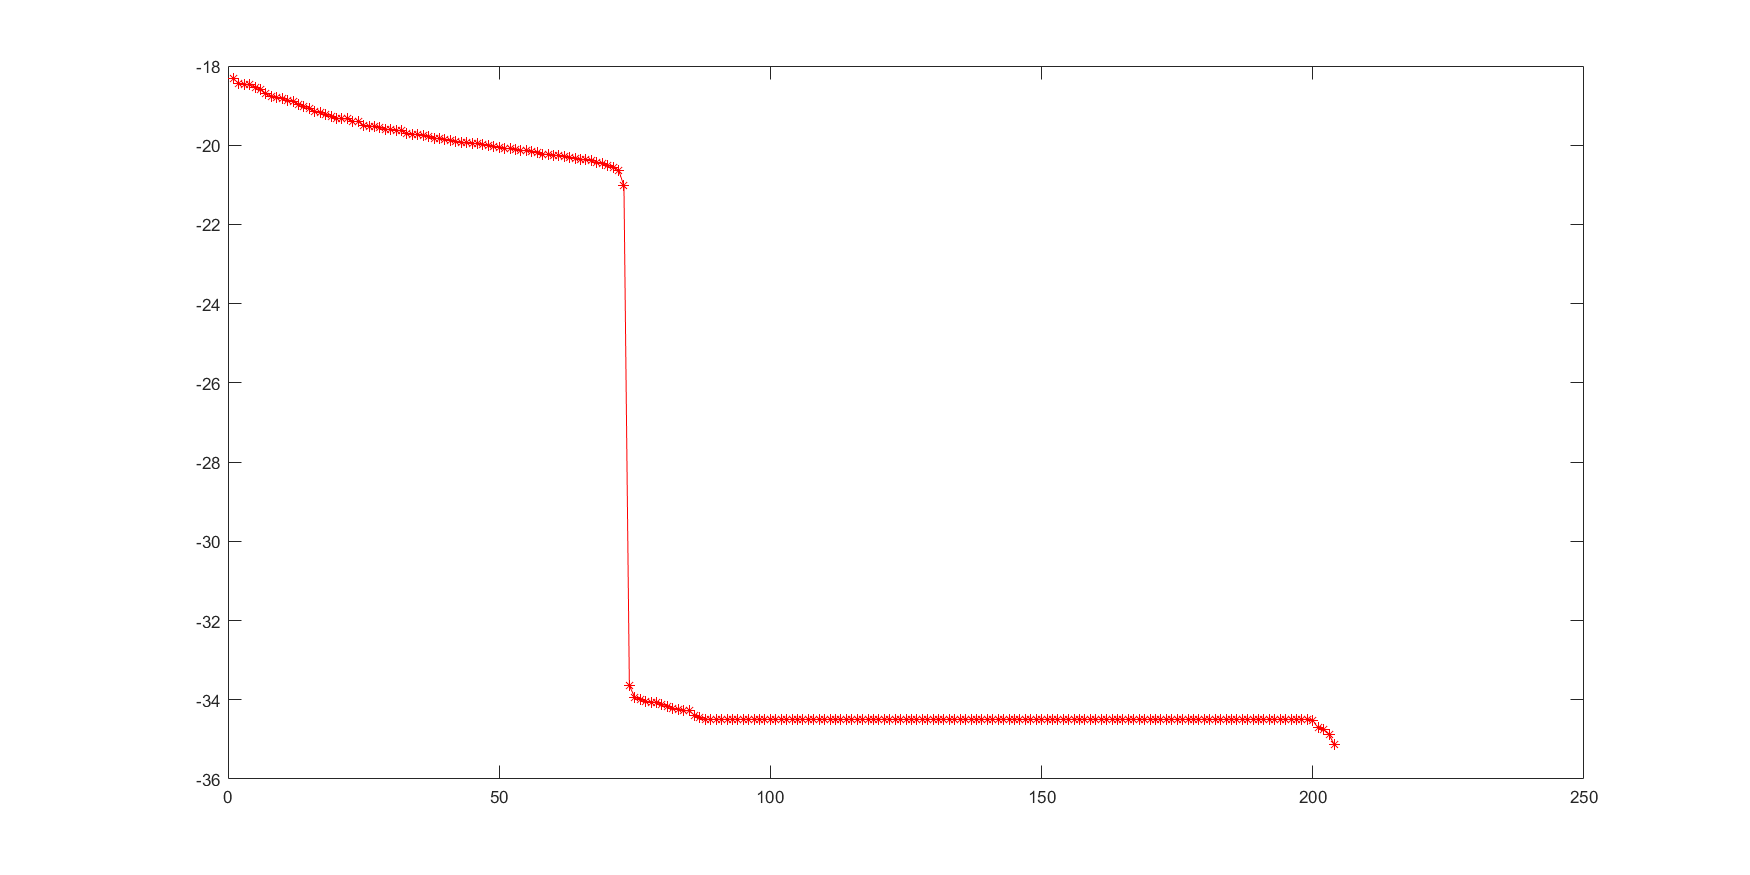

[u,s,v] = svd(planar_filt.trial{1}*planar_filt.trial{1}');
plot(log10(diag(s)),'-r*');

The next step is then the decomposition of the data by an ICA method ('runica') originally developed for EEGLAB and imported into Fieldtrip. The 'runica' method is an implementation of the infomax ICA algorithm proposed by Bell & Sejnowski (1995) with the natural gradient feature of Amari, Cichocki & Yang (1996). We will also specify the rank of the data ('cfg.numcomponent'). 

cfg        = [];  
cfg.method = 'runica';  
cfg.numcomponent = data_rank;
planar_comp = ft_componentanalysis(cfg,planar_filt);   

the input is raw data with 204 channels and 310 trials
the call to "ft_selectdata" took 0 seconds
baseline correcting data 
scaling data with 1 over 0.000000
concatenating data
concatenating trials...
Concatenating trial 310 from 310

concatenated data matrix size 204x279000
starting decomposition using runica



Input data size [73,279000] = 73 channels, 279000 frames
After PCA dimension reduction,
  finding 73 ICA components using logistic ICA.
Decomposing 52 frames per ICA weight ((5329)^2 = 279000 weights, Initial learning rate will be 0.001, block size 63.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -3.51327 to 3.93814
Reducing the data to 73 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ...
step 1 - lrate 0.001000, wchange 62.54730852, angledelta  0.0 deg
step 2 - lrate 0.001000, wchange 18.66573496, angledelta  0.0 deg
step 3 - lrate 0.001000, wchange 13.73610205, angledelta 92.1 deg
step 4 - lrate 0.000900, wchange 11.77469195, angledelta 103.9 deg

 In ft_apply_montage at line 114
 In ft_componentanalysis at line 917



 In ft_apply_montage at line 132
 In ft_componentanalysis at line 917

the call to "ft_componentanalysis" took 73 seconds


The output structure has a few new fields, the most important of which are the unmixing matrix (i.e. the ICA weights) and the 'topo' field (i.e., the mixing matrix). The 'trial' field now shows the time course of the ICA components for each trial.  

## **ICA step 2 - Identifying components**

The next step is to identify the ICA components corresponding to artifacts - in particular blinks, muscle and cardiac artifacts. Components which are identified as artifacts are then 'projected out' from the data.  

Here we plot the planar gradiometer topography to identify artifact components. To do so, we will use the 'ft_databrowser' function. By specifying 'cfg.viewmode' as 'component', 'ft_databrowser'  will plot the ICA components as topographies and time courses. 'cfg.channel' specifies the components to display (in our case, the  first 10). By specifying the planar gradiometer layout ('neuromag306planar.lay'), 'ft_databrowser' displays the gradiometer  topography of the MEGIN TRIUX system. 

undoing the comp balancing for the gradiometer definition


 In ft_databrowser at line 338

detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



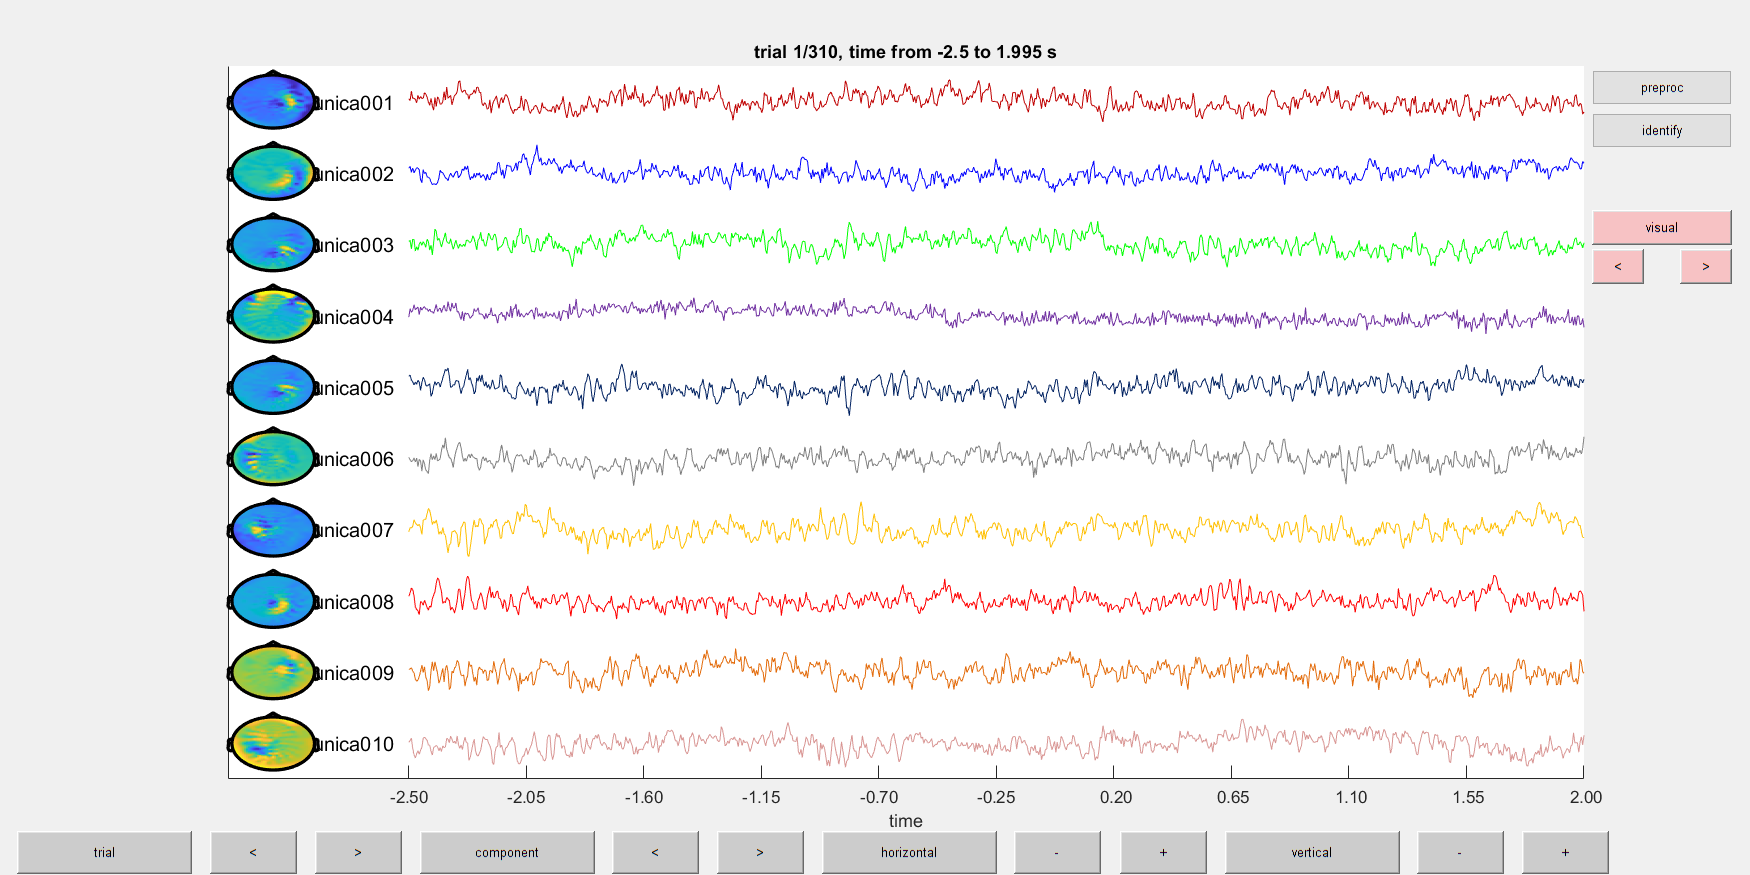

the call to "ft_databrowser" took 5 seconds


cfg = [];
cfg.channel = [1:10]; 
cfg.continuous='no';
cfg.viewmode = 'component'; 
cfg.layout = 'neuromag306planar.lay';
ft_databrowser(cfg, planar_comp);

By browsing the trials it comes clear that component #4 reflects eye blink (see, e.g. trial 119). Component #35 is a cardiac artifact. The other  components might not be artifact-related. As a rule of thumb, only reject components which clearly reflect artifacts identified from the respective time-course and topography.

### **Question 2**

Some of the components are likely to reflect oscillatory brain  activity. Identify some of these components and explain why they reflect brain oscillations.  

**IMPORTANT:** The ICA algorithm is not deterministic. That  means that the components will be produced in different order each time  'ft_componentanalysis' is called.

## **ICA Step 3 - Rejecting components**

To attenuate the identified artifact components, we specify the components that needs to be rejected in the 'cfg.component' field of  'ft_rejectcomponent'.

It should be noted that the projection is a simple matrix with no temporal information. It can therefore be applied to the original data.

cfg = [];  
cfg.component = [4 37];  
planar_ica = ft_rejectcomponent(cfg, planar_comp, planar_rjv1);

undoing the comp balancing for the gradiometer definition


 In ft_apply_montage at line 114
 In ft_rejectcomponent at line 202



 In ft_apply_montage at line 132
 In ft_rejectcomponent at line 202

the call to "ft_rejectcomponent" took 5 seconds


The resulting output structure (here called 'planar_ica') is the result of projecting out the components from the data. To illustrate the effect of the ICA rejection, the figures below (trial 119) show the data of two gradiometer channels which were strongly affected by eye blinks before and after the eye blink component rejection.

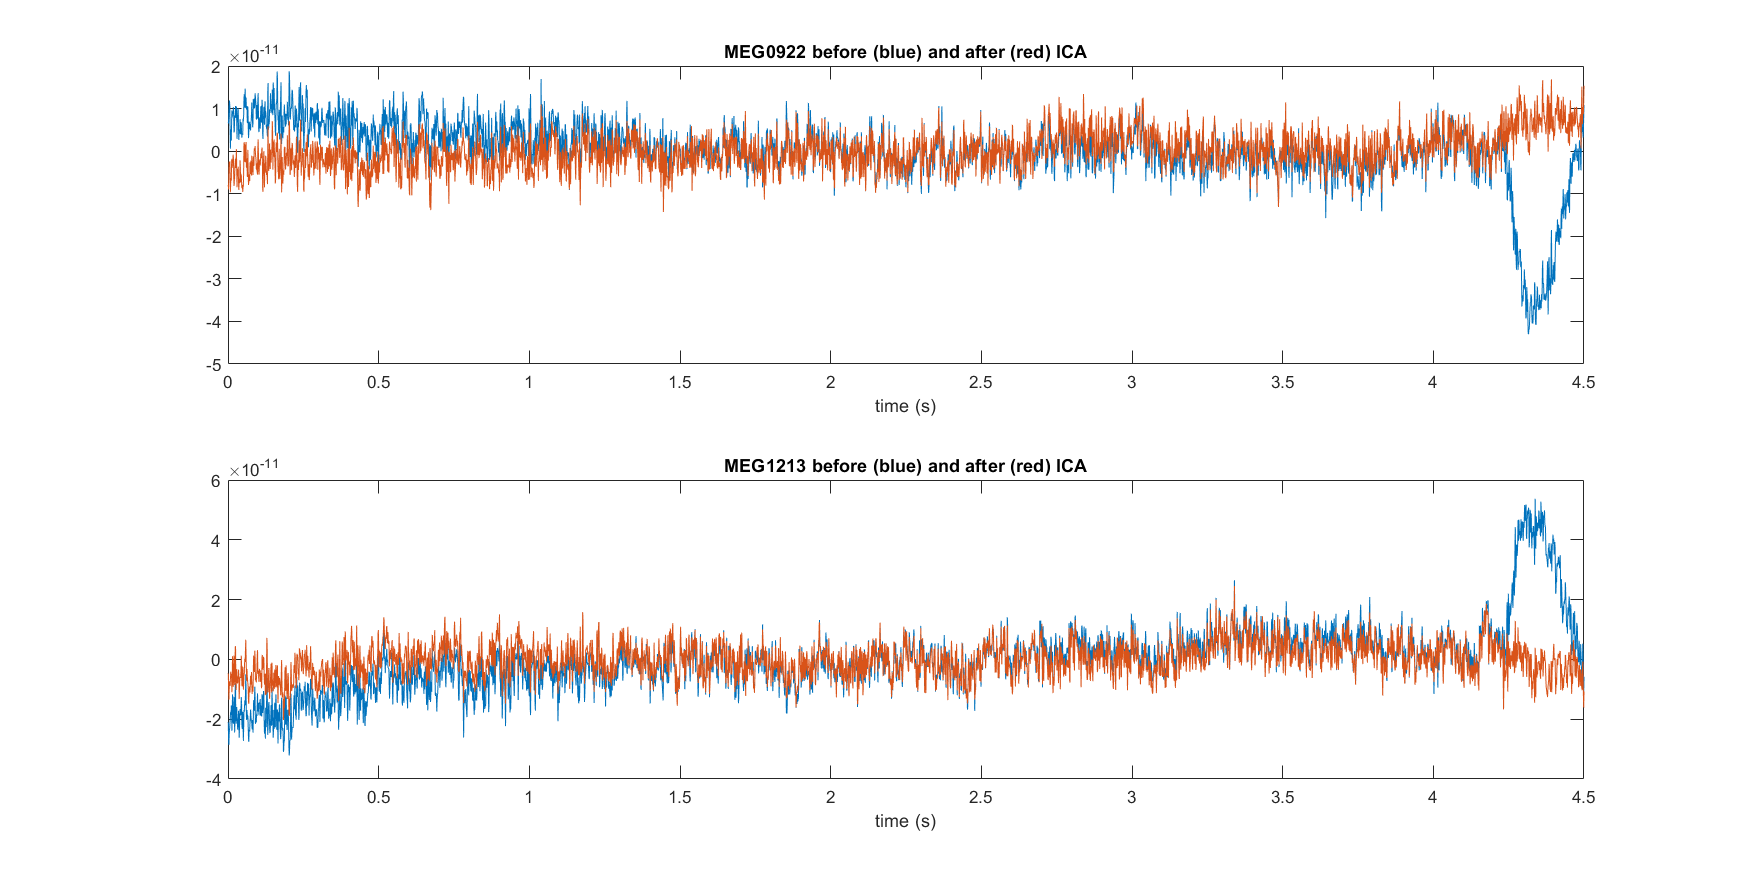

figure
subplot(2,1,1)
plot((1:length(planar_rjv1.trial{1,119}(63,:)))/1000,planar_rjv1.trial{1,119}(63,:),(1:length(planar_ica.trial{1,119}(63,:)))/1000,planar_ica.trial{1,119}(63,:))
xlabel('time (s)')
title('MEG0922 before (blue) and after (red) ICA')
subplot(2,1,2)
plot((1:length(planar_rjv1.trial{1,119}(86,:)))/1000,planar_rjv1.trial{1,119}(86,:),(1:length(planar_ica.trial{1,119}(86,:)))/1000,planar_ica.trial{1,119}(86,:))
xlabel('time (s)')
title('MEG1213 before (blue) and after (red) ICA')

## Further visual artefact rejection

To ensure that all artifacts have been removed or attenuated, it is advisable to go back to the semi-automatic artifact rejection step to check all the trials once more. Again, we keep a record of the trials ('trl_keep2.mat') we want to keep in the same way as we did during the first round of visual artifact rejection.

planar_ica.trialinfo(1:end,2)=1:length(planar_ica.trialinfo);  

We use 'ft_databrowser' to browse through the data trial-by-trial and select  with the mouse segments of data that are likely contaminated by artifacts. Then we remove entire trials where artifacts are selected with 'ft_rejectartifact'. 

cfg = [];
cfg.viewmode='vertical';
cfg.continuous='no';
artf=ft_databrowser(cfg, planar_ica);

the input is raw data with 204 channels and 310 trials


 In ft_databrowser at line 338

detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



the call to "ft_databrowser" took 211 seconds


planar_clean=ft_rejectartifact(artf,planar_ica)

 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 277
 In ft_rejectartifact at line 202



planar_clean = struct with fields:
         label: {204×1 cell}
          grad: [1×1 struct]
       fsample: 1000
           cfg: [1×1 struct]
           hdr: [1×1 struct]
         trial: {1×310 cell}
          time: {1×310 cell}
     trialinfo: [310×2 double]
    sampleinfo: [310×2 double]


Here we excluded 59 trials because of remaining - primarily muscle - artifacts. We keep the identifiers of the trials for later. 

trl_keep2=planar_clean.trialinfo(1:end,2);

Save the variable.

save([data_path,'trl_keep2.mat'],'trl_keep2')

Finally, it can be a good idea to save the structure containing the ICA components.  

save([data_path,'planar_comp.mat'], 'planar_comp')

## **Publications and preregistration**

**Pre-registration**:  ICA will be used to 'project out' artefacts. Prior to the ICA, downsampling will be performed to 200 Hz. The runica  algorithm will be applied. Ocular, cardiac and muscle artefacts will be  identified in the components based on time-course and topography. These  components will be projected out in the non-downsampled data.  

**Publications**: beyond the details above report the mean number of ICA components (incl. standard deviation) rejected in each subject.  

EXAMPLE: "The data were downsampled to 200Hz prior to Independet  Component Analysis (ICA). Next the 'runica' ICA algorithm (see Bell  & Sejnowski, 1995,  Amari, Cichocki & Yang, 1996) was applied on the segmented data as implemented in Fieldtrip. Clear  components containing cardiac artifacts and eyeblinks were removed in each subject  (XX+/-YY over subjects)." 

## **References**

Bell, A. J., & Sejnowski, T. J. (1995). An  information-maximization approach to blind separation and blind  deconvolution. Neural computation, 7(6), 1129-1159. 

Amari, S. I., Cichocki, A., & Yang, H. H. (1996). A new learning  algorithm for blind signal separation. In Advances in neural information processing systems (pp. 757-763). 